close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
dati=readtable('./data/MiniProjectEFSA.xlsx', opts);
dati.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

dose=[0, 30, 100, 150];

dati_male_1 = dati(dati.endpoint==1&dati.sex==0,:);
dati_female_1 = dati(dati.endpoint==1&dati.sex==1,:);
dati_male_2 = dati(dati.endpoint==2&dati.sex==0,:);
dati_female_2 = dati(dati.endpoint==2&dati.sex==1,:);
dati_male_3 = dati(dati.endpoint==3&dati.sex==0,:);
dati_female_3 = dati(dati.endpoint==3&dati.sex==1,:);

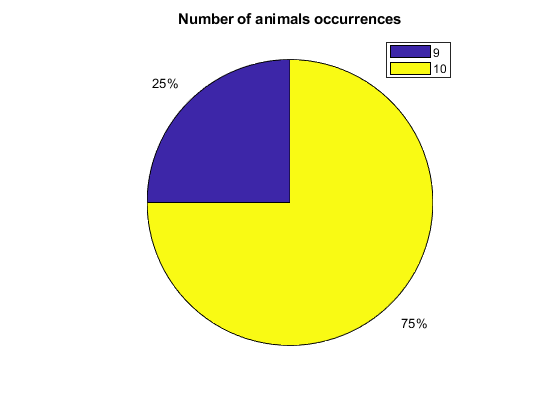

figure
pie(groupcounts(dati.numberOfAnimals),"%.f%%")
title('Number of animals occurrences')
legend("9","10")

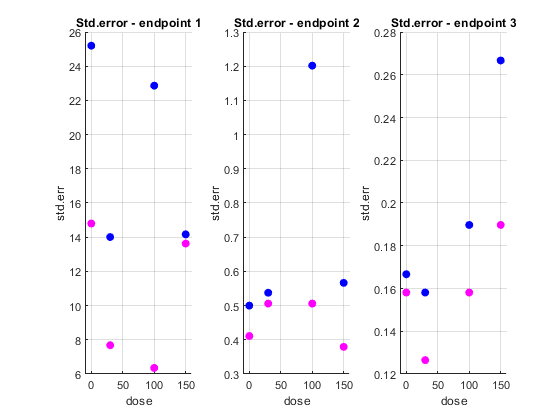

figure
subplot(1,3,1)
scatter(dose,dati_male_1.SD./sqrt(dati_male_1.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,dati_female_1.SD./sqrt(dati_female_1.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 1")
xlabel("dose")
ylabel("std.err")

subplot(1,3,2)
scatter(dose,dati_male_2.SD./sqrt(dati_male_2.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,dati_female_2.SD./sqrt(dati_female_2.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 2")
xlabel("dose")
ylabel("std.err")

subplot(1,3,3)
scatter(dose,dati_male_3.SD./sqrt(dati_male_3.numberOfAnimals),'blue',"filled")
hold on
scatter(dose,dati_female_3.SD./sqrt(dati_female_3.numberOfAnimals),'magenta',"filled")
grid on
xlim([-10 160])
title("Std.error - endpoint 3")
xlabel("dose")
ylabel("std.err")

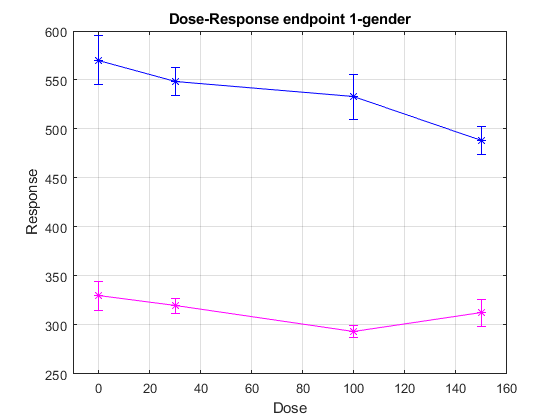

%% Plotting dose-responde for endpoint-gender

%Endpoint 1
figure
errorbar(dose,dati_male_1.response,dati_male_1.SD./sqrt(dati_male_1.numberOfAnimals),"-*b")
xlim([-10 160])
grid on
hold on
errorbar(dose,dati_female_1.response,dati_female_1.SD./sqrt(dati_female_1.numberOfAnimals),"-*m")
title('Dose-Response endpoint 1-gender')
xlabel('Dose')
ylabel('Response')

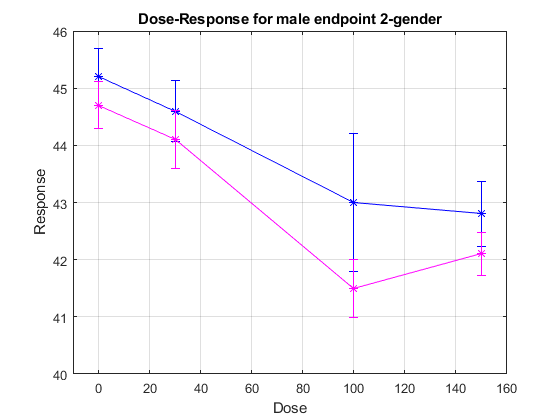

%Endpoint 2 
figure
errorbar(dose,dati_male_2.response,dati_male_2.SD./sqrt(dati_male_2.numberOfAnimals),"-*b")
grid on
hold on
errorbar(dose,dati_female_2.response,dati_female_2.SD./sqrt(dati_female_2.numberOfAnimals),"-*m")
xlim([-10 160])
title('Dose-Response for male endpoint 2-gender')
xlabel('Dose')
ylabel('Response')

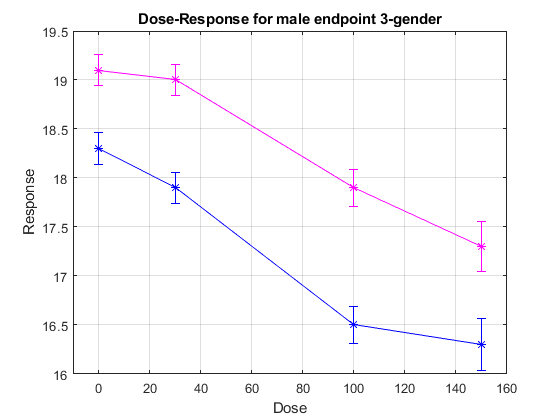

%Endpoint 3
figure
errorbar(dose,dati_male_3.response,dati_male_3.SD./sqrt(dati_male_3.numberOfAnimals),"-*b")
grid on
hold on
errorbar(dose,dati_female_3.response,dati_male_3.SD./sqrt(dati_female_3.numberOfAnimals),"-*m")
xlim([-10 160])
title('Dose-Response for male endpoint 3-gender')
xlabel('Dose')
ylabel('Response')